format long
clear

[x1,y1] = Euler_explicito_simple('funcion_simple',0,3,2,1)

x1 =                    0
   1.500000000000000
   3.000000000000000


y1 =    1.000000000000000
   2.500000000000000
  -5.000000000000000


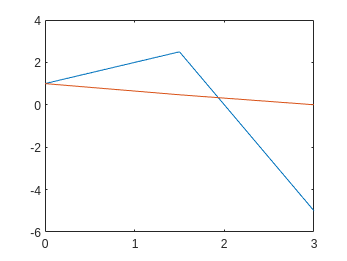

%%% graficar solucion
%solex = exp(-10*x1)
solex = exp((1/4) - ((1/2)-x1).^2);
plot(x1,y1)
hold on
plot(x1, solex)
hold off

n=0:5;
N=2*2.^n;

[x1,y1] = Euler_explicito_simple('funcion_simple',0,3,N(1),1);
solex1 = exp((1/4) - ((1/2)-x1).^2);

error_vec=zeros(6,1);
error_vec(1) = max(abs(y1-solex1));

for j=2:6
    [xj, yj] = Euler_explicito_simple('funcion_simple',0,3,N(j),1);
    solexj = exp((1/4) - ((1/2)-xj).^2);
    error_vec(j) = max(abs(yj-solexj));
    error_vec(j-1)/error_vec(j)
end

ans =    5.644908116911592


ans =    2.509688779890399


ans =    2.091888007608998


ans =    2.060493877782196


ans =    2.031586544244115
